clear all
close all
clc

rng(1);

load('Benchmark_EEG_medium')


Preprocessing Data

partici = 1    %Choose participant

partici = 1


[input,output] = cleanEEG(EEGdata,partici);   %Clean data, normalize and sort input and output signal



Choose lags

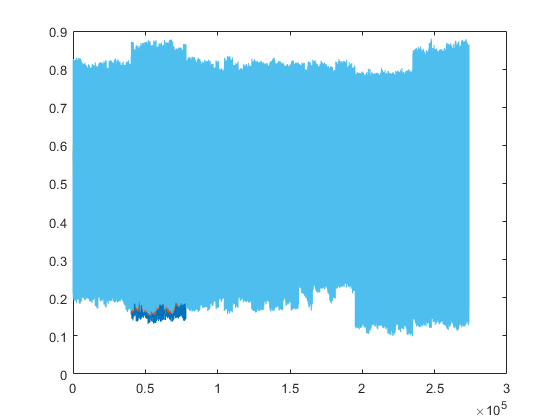

%angle
inlags=[6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-201:end-inlags(l)-1,:), [],1));
end

%angular velocity
vlags=[10 9 8 6 5 4];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-201:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-200:end-vlags(l),:), [],1))/0.2+0.5;
end

plot(v)


%output
outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-200:end-outlags(l),:), [],1);
end


Split test and training set

testind = [20000:20255 60000:60255 10000:10255 130000:130255 170000:170255 200000:200255 240000:240255];
trainind = setdiff([1:size(u,1)],testind);

featurez = [u(trainind,:) v(trainind,:) y(trainind,2:end)];
zeta = y(trainind,1);

tfeaturez = [u(testind,:) v(testind,:) y(testind,2:end)];
yt = y(testind,1);

% tfeaturez = featurez(1:400,:);
% yt = zeta(1:400,:);

Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                 %degree B-spline
m = 4;                  %Number of knot intervals
In = n+m;               %Number of B-splines

un = basisvectors(featurez,n,m);



Initialize tensor train

% Choose TT-ranks
maxrank = 10;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank))

r =      1     6    10    10    10    10    10    10    10    10    10    10    10     6     1



[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 8.6672e-08


Optimize TT cores

lambda=10^-5

lambda = 1.0000e-05

difforder=2;
MAXITR = d;

nselect = floor(logspace(log10(dof*2/N),0,MAXITR)*0.5*N);

% MAXITR = 2;
% nselect = ones([1,MAXITR])*N

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);

plot(res1)
plot(res2)

res1(end)

Evaluate Test data

yhat = evalspline(TN,tfeaturez,n,m);


erboi = (yhat-yt);
histogram((erboi)');
VAF = 1-var(erboi)/var(yt)
MSE = immse(yhat,yt)

figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 256 -inf inf])

%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FY(1:floor(end/2)))
plot(FZ(1:floor(end/2)))
hold off

